WeightedLOB = readtable('weightedLOB.csv');

% Feature Engineering
% Create features and target variables
features = table();
features.SourceTime = WeightedLOB.SourceTime;
features.Weighted_Bid_Price = WeightedLOB.Weighted_Bid_Price;
features.Weighted_Ask_Price = WeightedLOB.Weighted_Ask_Price;
features.MidPrice = WeightedLOB.MidPrice;

% Create lagged features (previous 30 minutes)
windowSize = 30 * 60; % 30 minutes in seconds
features.LaggedWeightedBid = lagmatrix(WeightedLOB.Weighted_Bid_Price, 1:windowSize);
features.LaggedWeightedAsk = lagmatrix(WeightedLOB.Weighted_Ask_Price, 1:windowSize);
features.LaggedMidPrice = lagmatrix(WeightedLOB.MidPrice, 1:windowSize);

% Shift the State column to represent the next 10 seconds' state
features.TargetState = circshift(WeightedLOB.State, -10);

% Remove rows with NaN resulting from lag operations
features(any(isnan(features.LaggedWeightedBid), 2), :) = [];
features(any(isnan(features.LaggedWeightedAsk), 2), :) = [];
features(any(isnan(features.LaggedMidPrice), 2), :) = [];
% Assuming TargetState is categorical, we convert it to string to check for missing entries
features(any(ismissing(categorical(features.TargetState)), 2), :) = [];

% Split the data into training and testing sets
splitRatio = 0.8;
splitIndex = round(splitRatio * size(features, 1));
trainData = features(1:splitIndex, :);
testData = features(splitIndex+1:end, :);


% Train the SVM model
rng(1); % Set seed for reproducibility
X = [trainData.LaggedWeightedBid, trainData.LaggedWeightedAsk, trainData.LaggedMidPrice];
Y = categorical(trainData.TargetState);
svmModel = fitcecoc(X, Y);

% Predict on the test set
XTest = [testData.LaggedWeightedBid, testData.LaggedWeightedAsk, testData.LaggedMidPrice];
YTestPred = predict(svmModel, XTest);


% Evaluate the accuracy
ts = categorical(testData.TargetState);
result = table(ts, YTestPred, 'VariableNames',{'Test_TargetState', 'Prediction'})

result = 2336×2 table
    Test_TargetState    Prediction
    ________________    __________

         Down              Up     
         Up                Down   
         Down              Down   
         Down              Down   
         Up                Down   
         Down              Down   
         Down              Down   
         Up                Down   
         Down              Down   
         Up                Down   
         Up                Up     
         Up                Up     
         Up                Up     
         Up                Up     
         Static            Up     
         Down              Down   


accuracy = sum(result.Test_TargetState == result.Prediction)/length(result.Prediction)

accuracy = 0.4944

disp(['Accuracy on Test Set: ' num2str(accuracy)]);

Accuracy on Test Set: 0.49443


% Evaluate the confusion matrix
confMat = confusionmat(ts, YTestPred);

% Extract the scores
truePositive = confMat(1, 1);
trueNegative = confMat(2, 2);
falsePositive = confMat(2, 1);
falseNegative = confMat(1, 2);

disp(['True Positive: ' num2str(truePositive)]);

True Positive: 595


disp(['True Negative: ' num2str(trueNegative)]);

True Negative: 0


disp(['False Positive: ' num2str(falsePositive)]);

False Positive: 12


disp(['False Negative: ' num2str(falseNegative)]);

False Negative: 0



% Calculate Accuracy, Precision, Recall, and F1 Score

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
f1Score = 2 * (precision * recall) / (precision + recall);

% Create a figure for the confusion matrix chart
figure;


disp(['Accuracy: ' num2str(accuracy)]);

Accuracy: 0.49443


disp(['Precision: ' num2str(precision)]);

Precision: 0.98023


disp(['Recall: ' num2str(recall)]);

Recall: 1


disp(['F1 Score: ' num2str(f1Score)]);

F1 Score: 0.99002



% Create a table with scores
scoreTable = table(accuracy, precision, recall, f1Score, 'VariableNames', {'Accuracy', 'Precision', 'Recall', 'F1Score'});
disp(scoreTable)

    Accuracy    Precision    Recall    F1Score
    ________    _________    ______    _______

    0.49443      0.98023       1       0.99002



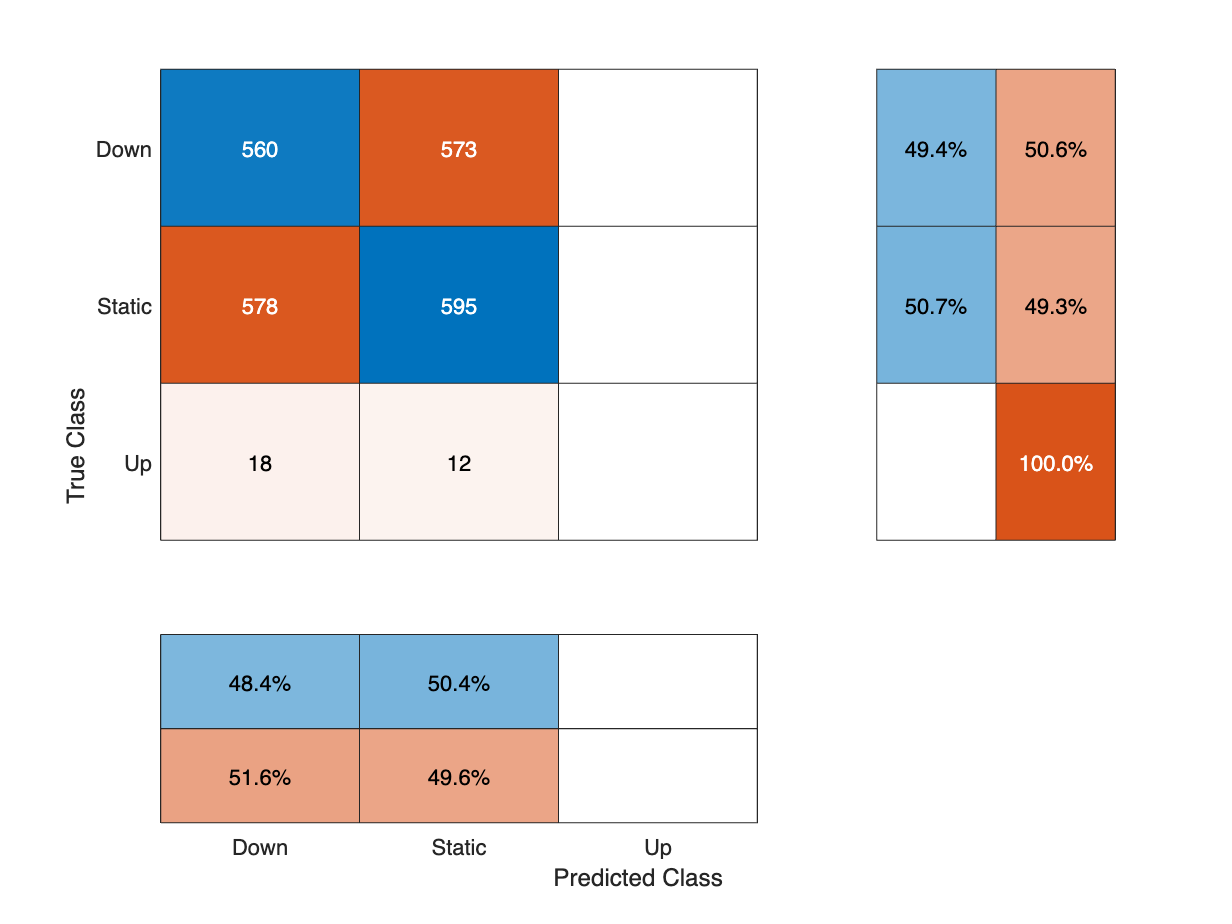

% Create a confusion matrix chart
figure;
confusionchart(confMat, {'Static', 'Up', 'Down'}, 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');